- importGeometry(从STL导入2D或者3D几何)

importGeometry(model,geometryfile)

gd = importGeometry(model,geometryfile)

`importGeometry(`[`model`](https://ww2.mathworks.cn/help/pde/ug/pde.pdemodel.importgeometry.html#bulkov_-1_sep_mw_c7b473f3-2ae0-476d-9c3e-96311b90ed6f)`,`[`geometryfile`](https://ww2.mathworks.cn/help/pde/ug/pde.pdemodel.importgeometry.html#bulkov_-1-geometryfile)`)` 从指定的STL几何文件创建几何容器，并将几何包含在`model`容器中。

[`gd`](https://ww2.mathworks.cn/help/pde/ug/pde.pdemodel.importgeometry.html#bulkov_-1-gd) `= importGeometry(`[`model`](https://ww2.mathworks.cn/help/pde/ug/pde.pdemodel.importgeometry.html#bulkov_-1_sep_mw_c7b473f3-2ae0-476d-9c3e-96311b90ed6f)`,`[`geometryfile`](https://ww2.mathworks.cn/help/pde/ug/pde.pdemodel.importgeometry.html#bulkov_-1-geometryfile)`)` 也返回几何到MATLAB ®工作区。

1.1 导入3D模型

model= createpde(3)

model =   PDEModel - 属性:

           PDESystemSize: 3
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


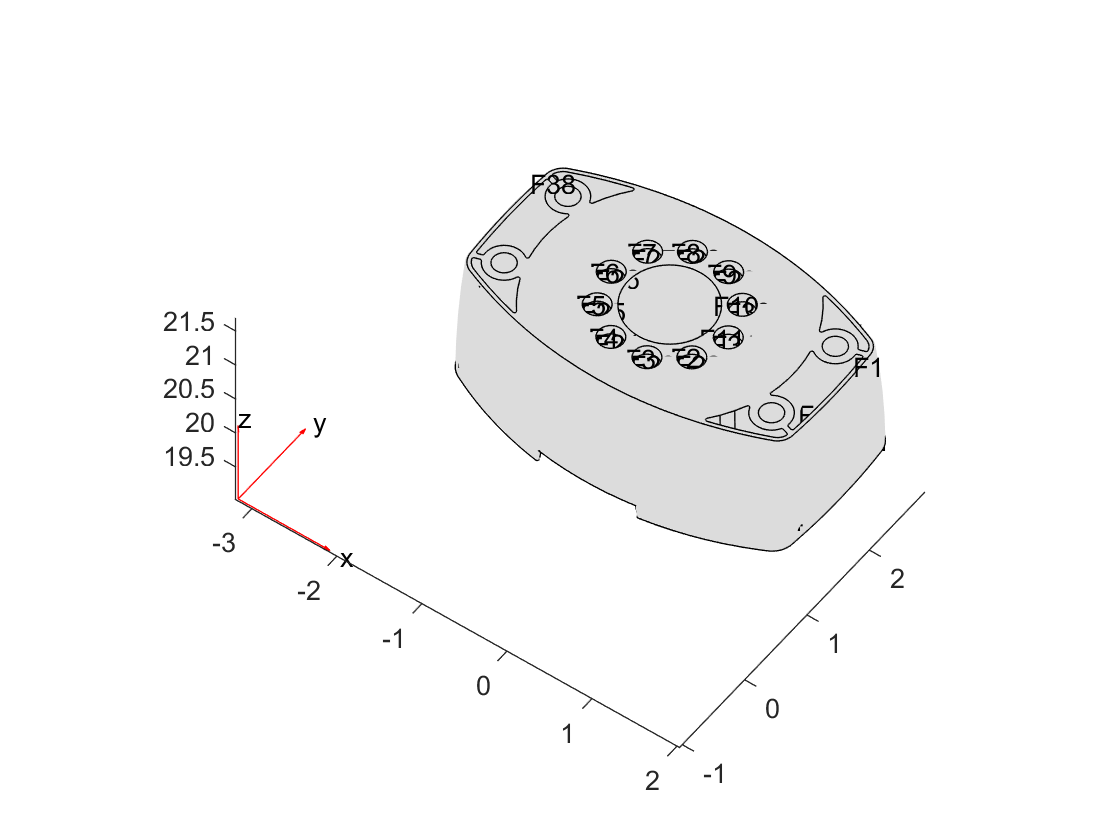

importGeometry(model,'D:\structure_heat\Structural_Thermal_PDE_with_MATLAB_Files\Demo_Files\YouBotThermalAnalysis\Gripper Pivot.stl');
pdegplot(model,'FaceLabels','on')

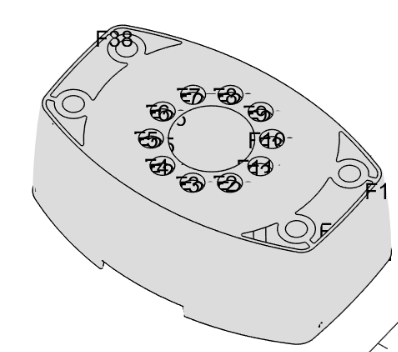p

1.2 导入2D模型

model= createpde;
importGeometry(model,'2D.stl');
pdegplot(model,'EdgeLabels','on')

Model object, specified as a `PDEModel` object, `ThermalModel` object, or `StructuralModel` object.

**Example:** `model = createpde(1)`

**Example:** `thermalmodel = createpde('thermal','steadystate')`

**Example:** `structuralmodel = createpde('structural','static-solid')`